## Three-phase power transmission system

powersysModel = "PowerTransmissionModel.slx";
open_system(powersysModel);

## Generate training data

 close_system(powersysModel,0);
trainModel = "TrainingModel.slx";
open_system(trainModel);

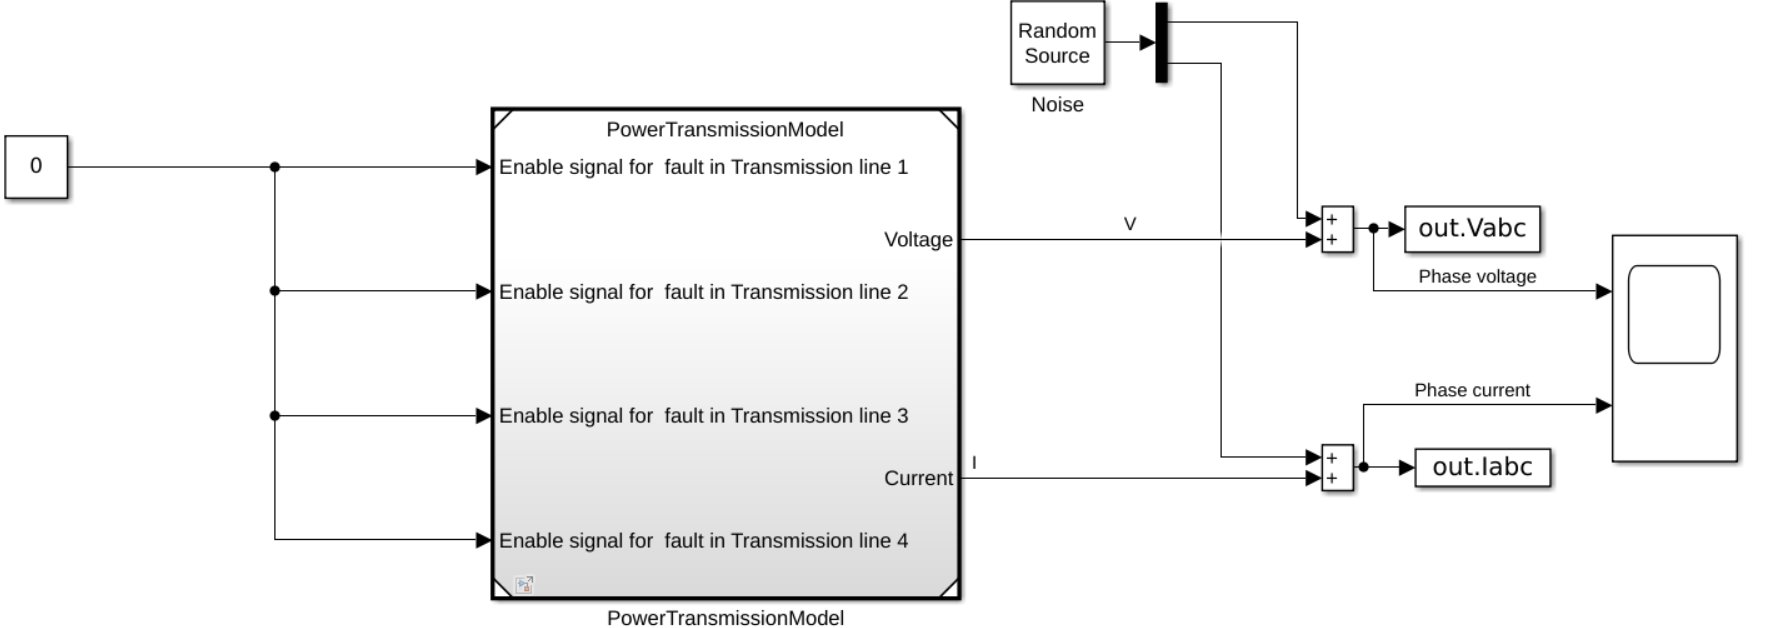

out = sim(trainModel);
close_system(trainModel,0);

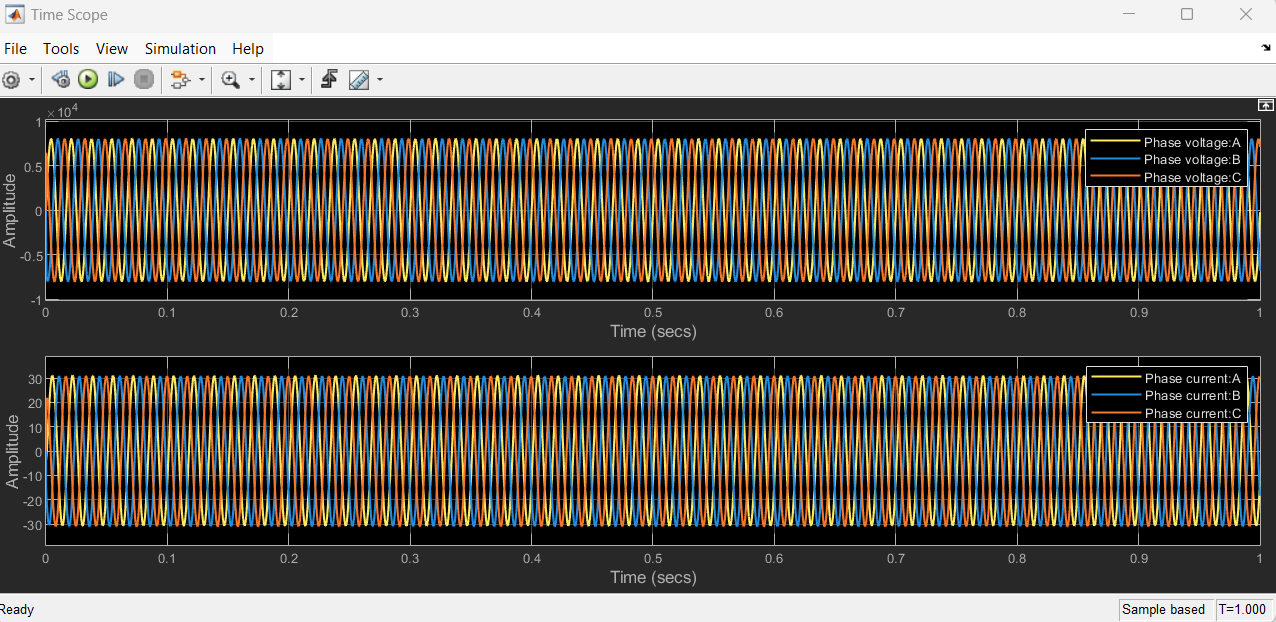

 Vabc = out.Vabc; 
Iabc = out.Iabc;

stdV = std(Vabc(:));
stdI = std(Iabc(:));

% Normalize voltages and currents
Vabc = Vabc/stdV;
Iabc = Iabc/stdI;

% Combine normalized voltage and currents
VInorm = [Vabc Iabc];

## Part 1: Detect fault in three-phase transmission line

detector = deepSignalAnomalyDetector(6,"lstm",EncoderHiddenUnits=32 ,...
    DecoderHiddenUnits=32, WindowLength=50,ThresholdMethod="max",ThresholdParameter=2);

% Set training options
sequenceLength = 64;
options = trainingOptions("adam", ...
    MaxEpochs=100, ...
    SequenceLength=sequenceLength,...
    Plots="training-progress");

% Train the detector
trainNow = false;
if trainNow
    trainDetector(detector,VInorm,options);
end

 if trainNow
    saveModel(detector,"threePhaseFaultDetector.mat");
end

### Fault detection in Simulink

 detectionModel = "FaultDetectionModel";
open_system(detectionModel);

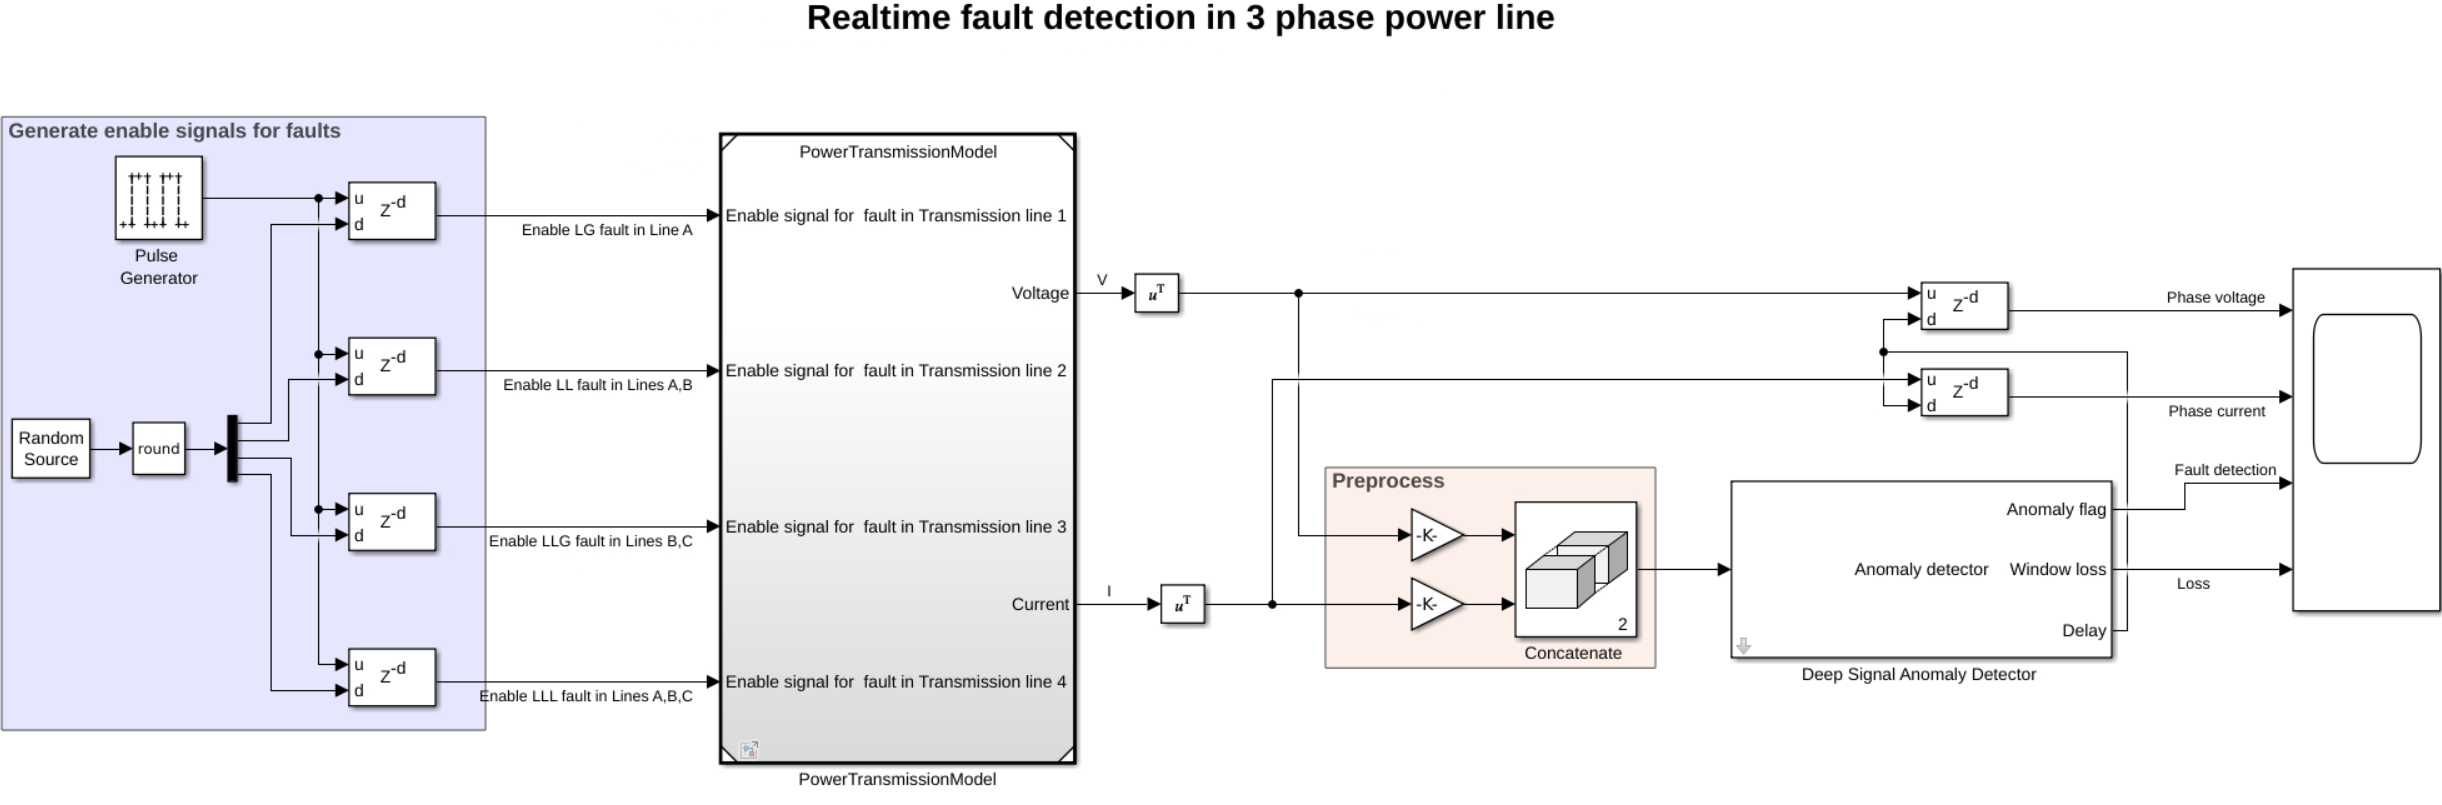

#### Fault generation

- L-G fault in a random interval of duration 0.1 second between simulation times 0 and 0.5 seconds in Phase A

- L-L fault in a random interval of duration 0.1 second between simulation times 0.5 and 1 seconds in Phases A,B

- L-L-G fault in a random interval of duration 0.1 second between simulation times 1 and 1.5 seconds in Phases B,C 

- L-L-L fault in a random interval of duration 0.1 second between simulation times 1.5 and 2 seconds in Phases A,B,C

#### Anomaly detection

sim(detectionModel);

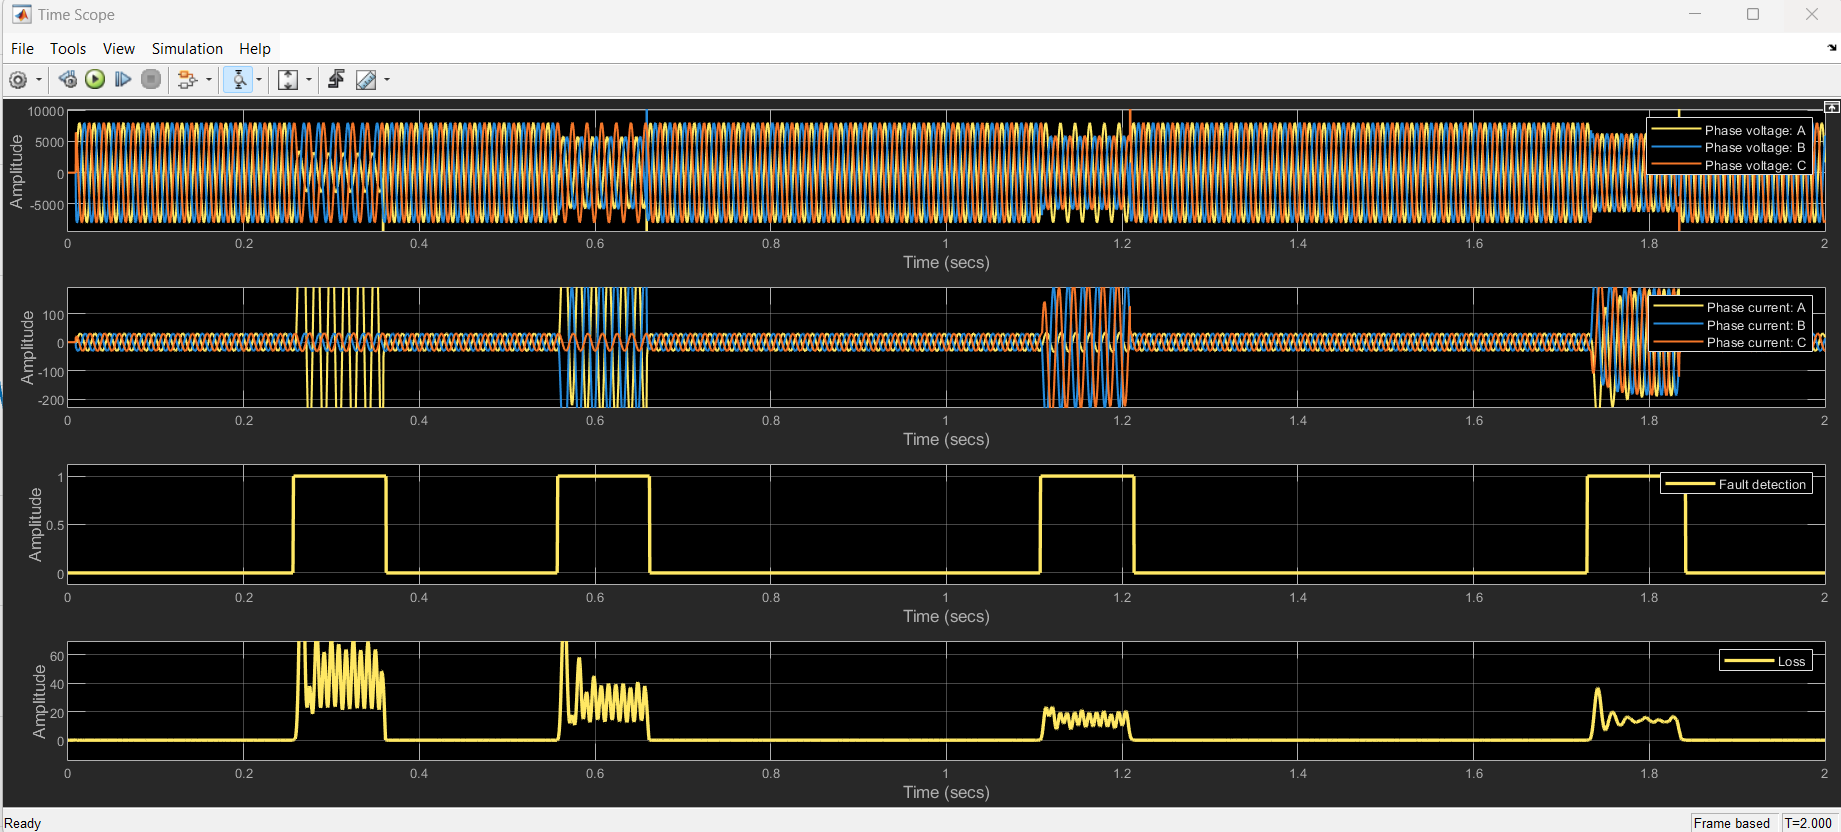

## Part 2 : Localize faults in three-phase transmission line

VINormCell = {VInorm(:,[1,4]), VInorm(:,[2,5]), VInorm(:,[3,6])};

localizer = deepSignalAnomalyDetector(2,"lstm",EncoderHiddenUnits=32 ,...
    DecoderHiddenUnits=32, WindowLength=50,ThresholdMethod="max",ThresholdParameter=2);

options.MaxEpochs = 50;
% Train the detector
if trainNow
    trainDetector(localizer,VINormCell,options);
end

 if trainNow
    saveModel(localizer,"threePhaseFaultLocalizer.mat");
end

### Fault detection and localization in Simulink

close_system(detectionModel,0);
localizationModel = "FaultLocalizationModel";
open_system(localizationModel);

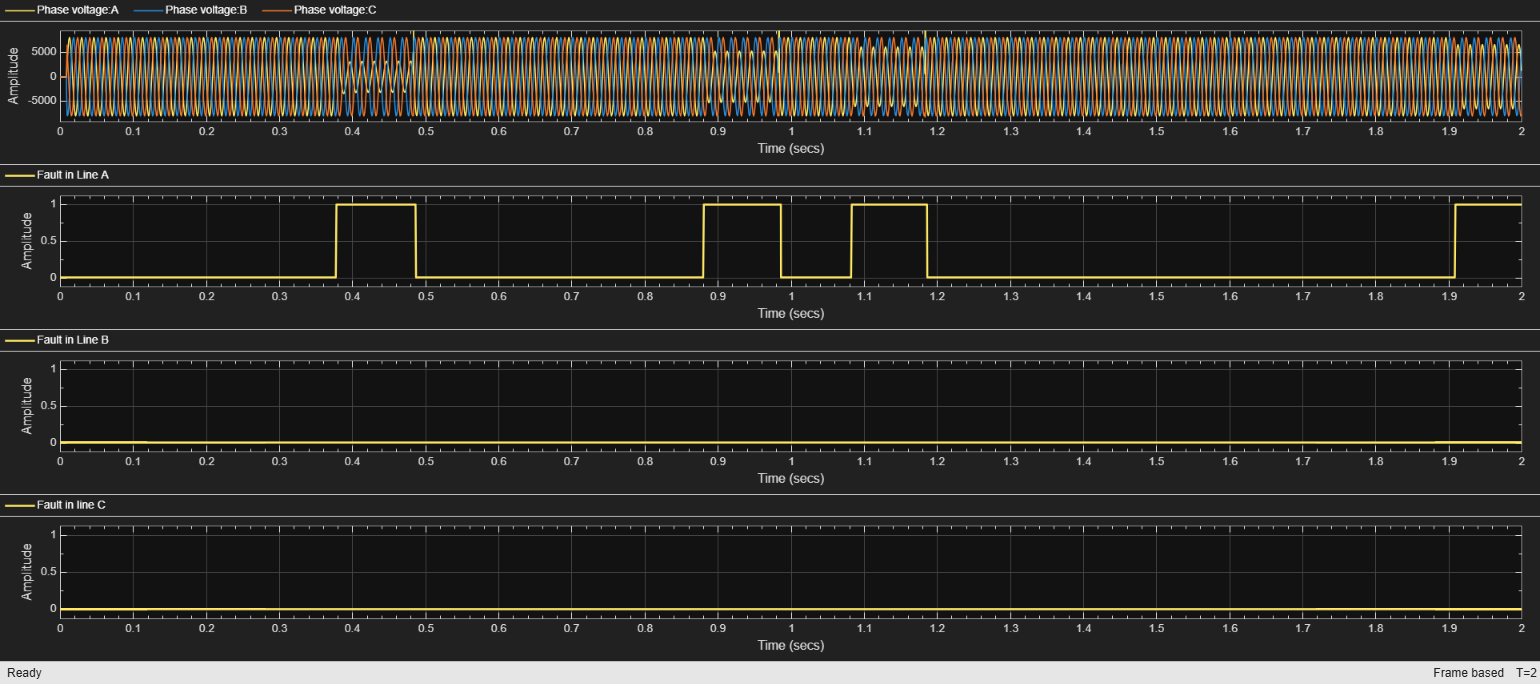

sim(localizationModel);

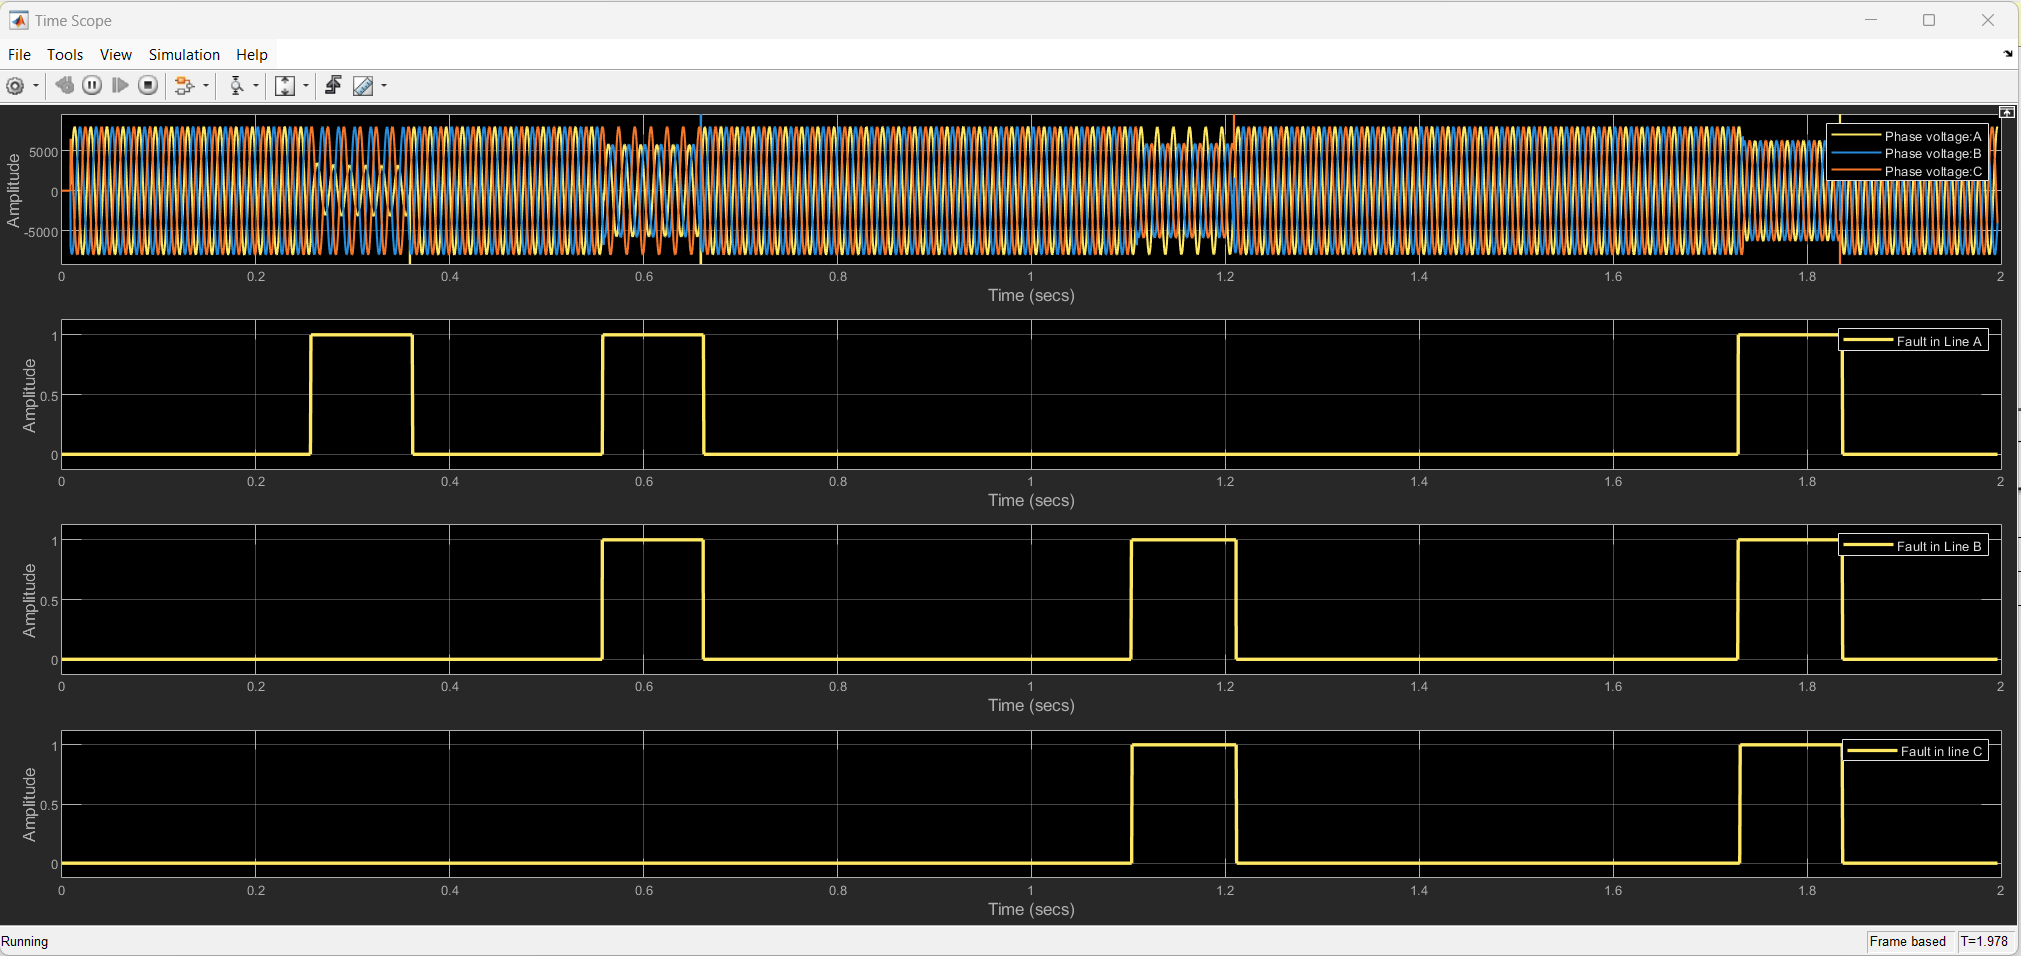

close_system(localizationModel,0);